# Kinematics Review

### **In Water**

For a chunk of water


$$\sum F = 0$$
 
$$\rightarrow$$
  
$$F_{b} - m_{chunk}g = 0$$
 
$$\rightarrow$$
 
$$F_{b} = m_{chunk}g$$
  
$$\rightarrow$$
 
$$m_{chunk} = \rho_{chunk}V_{chunk}$$



$$V_{chunk} = V_{object}$$
 
$$\rightarrow$$
 
$$\rho_{chunk} = \rho_{water}$$
  
$$\rightarrow$$
  
$$F_{b} = \rho_{w}V_{obj}g$$


To note

Object launched at an angle with drag force

- If we know it reaches terminal velocity at some point

- And you want to know how far it goes

- And you have X equation of motion

- You can just plug t = very large 

- And you have your x max

syms g m rho_r V_r v_T v v_0 v_f theta;

expr = v/(1 + (rho_r*V_r*v)/(m*v_T))

$$expr = \frac{v}{\frac{V_{r}\,\rho_{r}\,v}{m\,v_{T}}+1}$$

F = int(expr,v, [v_0, v_f])

$$F = \int_{v_{0}}^{v_{f}}\frac{v}{\frac{V_{r}\,\rho_{r}\,v}{m\,v_{T}}+1}\mathrm{d}v$$

% at y_max, v=0
%expr = subs(expr, v_f, 0)

syms p x x(t) h m g theta
assume(m>0)

dx = diff(x, t);
ddx = diff(x, t, 2);
T = m*dx^2;
U = h - m*g*x*sin(theta);

H = T+U;

% get dT/dx_dot = p
p = diff(subs(T, dx, sym('dx')), sym('dx'));
p = subs(p, sym('dx'), dx);
% write H in terms of 
H = sym('p')^2/(4*m) + U;
subs(H, sym('p'), p);
% get dH/dp = x_dot
x_dot = subs(diff(H, sym('p')), sym('p'), p);
% get -dH/dx = p_dot
dHdx = diff(subs(H, x, sym('x')), sym('x'));
EOM = -dHdx == diff(p);
EOM = simplify(EOM);
EOM = EOM/2;
x_dot = int(rhs(EOM), 0, t);
x = int(x_dot, 0, t);

**Matlab Examples for Quiz 1**

syms g r V_T y(t) y1(t) y2(t);

Tell matlab to define a variable for the first and second derivatives of y(t)

Dy = diff(y,t,1);
D2y = diff(y,t,2);

Define differentual equation to solve, initial conditions

equ = D2y == g*(1-r)*(1 - Dy^2/V_T^2);
cond = [y(0) == 0, Dy(0) == 0];
y1 = dsolve(equ, cond) % position y(t)

$$y1 = \frac{{V_{T}}^{2}\,\log\left({\tan\left(\frac{g\,t\,\sqrt{-{V_{T}}^{2}}\,\left(r-1\right)}{{V_{T}}^{2}}\right)}^{2}+1\right)}{2\,g\,\left(r-1\right)}$$

y2 = diff(y1, t) % velocity v(t)

$$y2 = \tan\left(\frac{g\,t\,\sqrt{-{V_{T}}^{2}}\,\left(r-1\right)}{{V_{T}}^{2}}\right)\,\sqrt{-{V_{T}}^{2}}$$

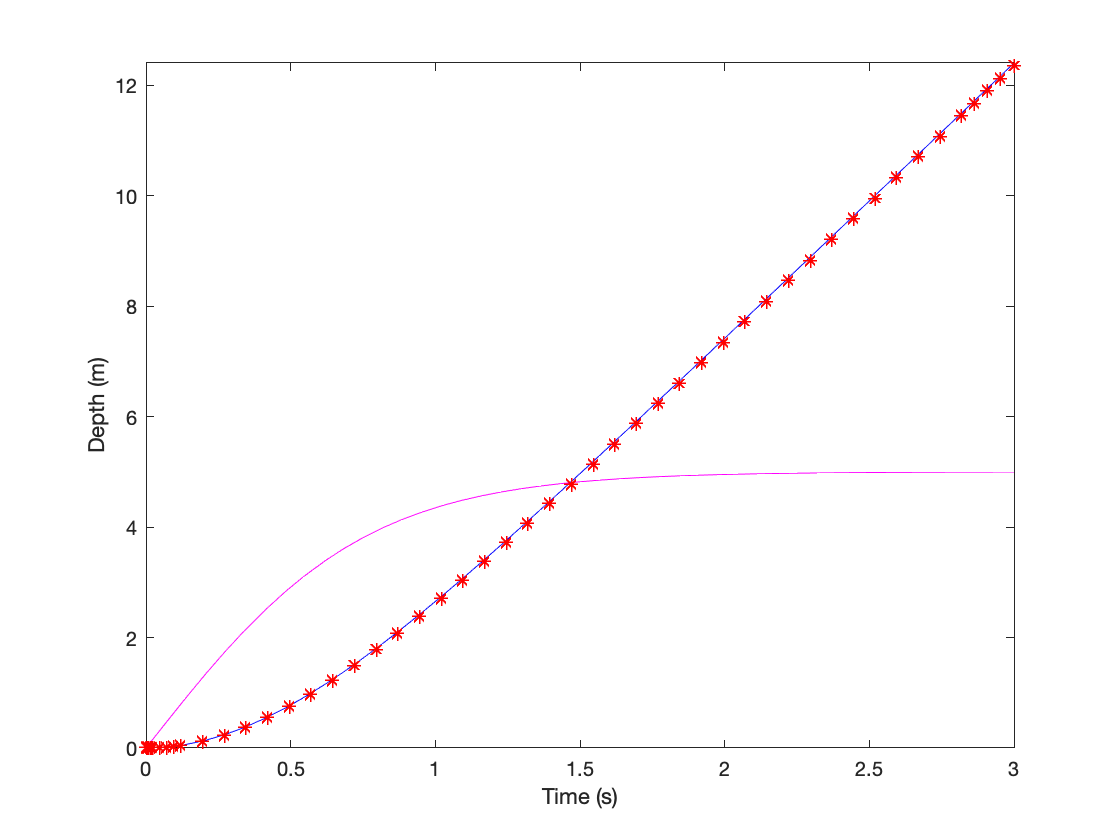

% To Plot: define numerical Variables
g = 10; %m/s
r = 1/3;
V_T = 5;
% define the equation Again
equn=D2y==g*(1-r)*(1-Dy^2/V_T^2);
y1=dsolve(equn,cond);
y2=diff(y1,t);
%Plot y(t) and v(t) for the first 3 seconds
fplot(y1,[0,3],'-b')
xlabel('time in seconds')
ylabel(['position in meters (blue/red), ...' ...
    'velocity in meters/second (red)'])
hold on
fplot(y2,[0,3],'-m')
% Using ODE45 for position
y_o = 0;
Dy_o = 0;
[t,y] = ode45(@ODE45UpwardFloat, [0 3],...
    [y_o; Dy_o]);
hold on
plot(t,y(:,1), '*r')
xlabel('Time (s)')
ylabel('Depth (m)')
hold on